## Compressed sensing in the spatial domain

The goal of this script is to demonstration compressed sensing image reconstruction of a synthetically generated ISAR image using Orthogonal Matching Pursuit (OMP). The image is extracted and a randomly sampled mask is applied to the image. 

Begin by extracting the ISAR image generated using run_simple_isar_bp. Apply a 2D Fourier transform to transform from the spatial domain to the spatial frequency domain. 

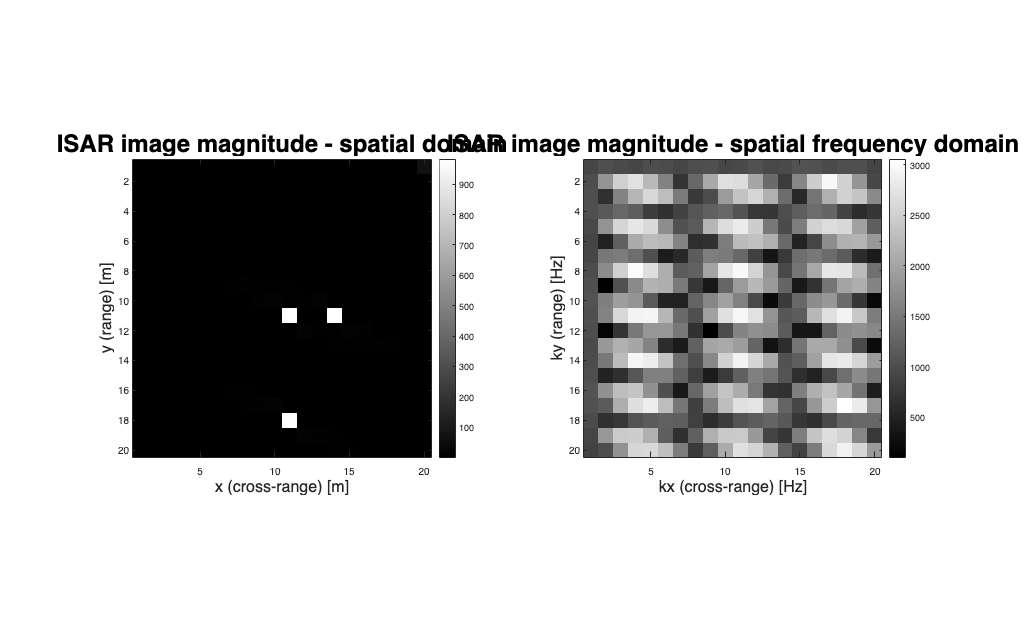

rng(0)

% load 2D ISAR image
x = load('data/rx_signal_bp_sd.mat');
x = x.rx_signal_bp;

% convert to the SFD
X = fftshift(fft2(x));

f = figure;
subplot(1,2,1)
imagesc(abs(x))
colormap("gray")
colorbar
xlabel('x (cross-range) [m]', 'FontSize', 16)
ylabel('y (range) [m]', 'FontSize', 16)
axis square
title('ISAR image magnitude - spatial domain', 'FontSize', 24)

subplot(1,2,2)
imagesc(abs(X))
colormap("gray")
colorbar
xlabel('kx (cross-range) [Hz]', 'FontSize', 16)
ylabel('ky (range) [Hz]', 'FontSize', 16)
axis square
title('ISAR image magnitude - spatial frequency domain', 'FontSize', 24)
set(gcf, 'Position', get(0, 'Screensize'));
saveas(f,'plots/sd_and_sfd_2D.png')

Generate a randomly sampled mask and apply it to the image in the spatial domain.

% extract dimensions from image
N = size(x,1);

% define the number of measurements
m = 200;

% randomly sample image (k-space)
mask = rand(m, N*N);
mask = mask > 0.5;

% vectorize the signal to apply a 1D OMP
x_vec = x(:);

Formulate the measured signal using y = Ax + n, where y is the measurement, A is the sensing matrix typically comprised of a sampling matrix $(\Phi)$ and a sparsifying basis $(\Psi)$, x is the desired signal and n is the noise. Because we will be attempting to reconstruct in the spatial domain, the sparsifying basis will be the identity matrix

% define sparsifying basis
Psi = eye(N*N);

% define sampling matrix (mask from previous section)
Phi = mask;

% create sensing matrix
A = Phi * Psi;

% define the std of the noise
sigma = 0.01;

% calculate the measurement
y = A * x_vec + sigma * randn(m,1);

%f=figure;
%imagesc(abs(reshape(y,m,N)))
%colormap("gray")
%colorbar
%xlabel('x (cross-range) [m]', 'FontSize', 16)
%ylabel('y (range) [m]', 'FontSize', 16)
%axis square
%set(gcf, 'Position', get(0, 'Screensize'));
%itle('Measured ISAR image magnitude with random sampling', 'FontSize', 24)
%saveas(f,'plots/meas_2D.png')

Apply OMP which assumes the columns of A are roughly orthogonal and form a basis: $A = [v_{1}, v_{2}, ..., v_{N}]$. The goal is to determine which of the basis vectors in A overlaps the most with the measurement. This overlap is determined by an inner product between the measurement and each basis vector: $<y,v_{n}> \forall n$. Select the basis vector with the greatest inner product, the greater the overlap. Approximate the signal by minimizing $||y - Ax||_{2}^{2}$ using the least squares approximation.

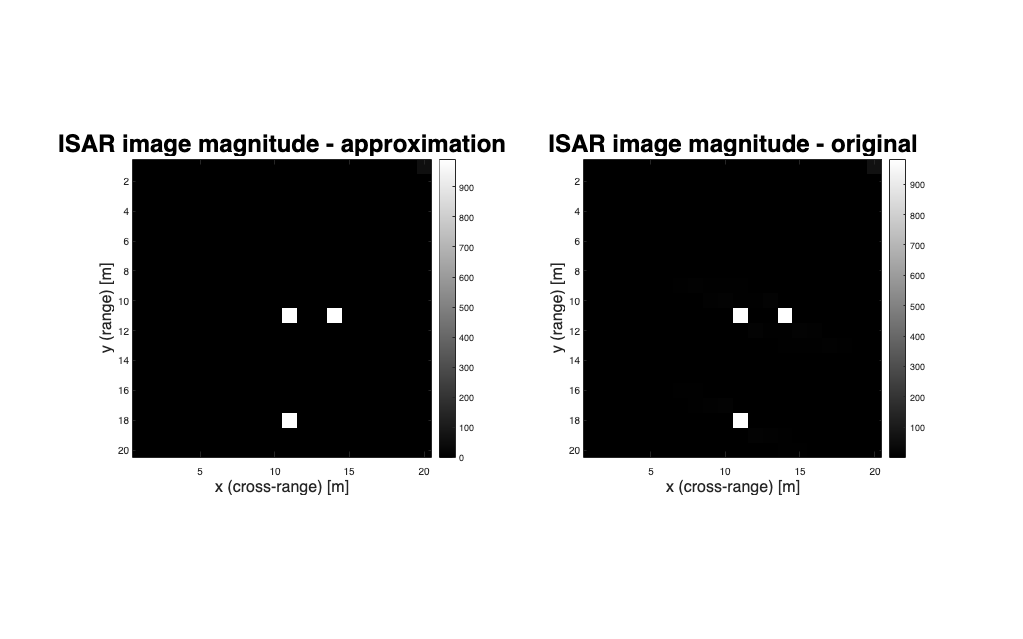

% initialize the array containing the approximate non-zero
% indices and the approxiximation
Lambda = []; x_hat = zeros(N*N,1);

% initialize the residual as the measurement
r = y;

for i = 1:4

    % inner product of the measurement and basis vectors
    c = A' * r;

    % find the index that maximizes the inner product
    [~, l] = max(abs(c));
    Lambda = [Lambda; l];

    % use this basis vector to calculate the least squares
    % solution
    x_hat(Lambda) = inv(A(:,Lambda)'*A(:,Lambda))*A(:,Lambda)'*y;
    r = y - A * x_hat;
end

f = figure;
subplot(1,2,1)
imagesc(abs(reshape(x_hat,N,N)))
colormap("gray")
colorbar
xlabel('x (cross-range) [m]', 'FontSize', 16)
ylabel('y (range) [m]', 'FontSize', 16)
axis square
title('ISAR image magnitude - approximation', 'FontSize', 24)

subplot(1,2,2)
imagesc(abs(x))
colormap("gray")
colorbar
xlabel('x (cross-range) [m]', 'FontSize', 16)
ylabel('y (range) [m]', 'FontSize', 16)
axis square
title('ISAR image magnitude - original', 'FontSize', 24)
set(gcf, 'Position', get(0, 'Screensize'));
saveas(f, 'plots/approx_2D.png')